%zad 2 (z ograniczeniami)
clear

x0 = [1,10,10,1];

fun = @ident;
nonlinfcn = @Hurwitz;
opts = optimoptions(@fmincon,'Display','iter','Algorithm','sqp');
opts = optimoptions('fmincon','Display','iter','Algorithm','sqp');
%x = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon,options)
x = fmincon(fun,x0,[],[],[],[],[],[],nonlinfcn,opts);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    1.201298e+02     2.220e-07     1.000e+00     0.000e+00     4.272e+01  
    1          12    1.069487e+02     1.829e-07     4.900e-01     5.074e+00     4.282e+02  
    2          19    7.514350e+01     1.478e-07     4.900e-01     3.632e+00     4.345e+01  
Objective function returned NaN; trying a new point...
    3          28    6.161446e+01     1.319e-07     2.401e-01     2.500e+00     1.094e+02  
    4          33    7.417177e+02     2.581e-08     1.000e+00     1.956e+02     2.682e+02  
    5          38    8.593032e+02     1.768e-08     1.000e+00     1.309e+02     1.346e+01  
    6          70    8.593032e+02     1.768e-08     1.104e-05     2.713e-04     1.346e+01  

Local minimum possible. Constraints


G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p;
G2=tf([0 1.25],[x(1) x(2) x(3) x(4)]) % dla  %c = []

G2 =
 
                   1.25
  ---------------------------------------
  294.4 s^3 + 148.5 s^2 + 59.28 s + 6.683
 
Continuous-time transfer function.



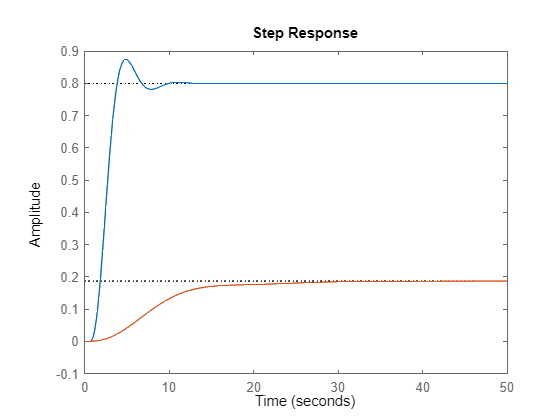

%G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])  % dla  c ;
step(G1,G2);


b=G2.Numerator{1, 1};
a=G2.Denominator{1,1};
[z,p,k] =tf2zp(b,a);

disp('-----------------')

-----------------


disp('Z ograniczeniami: ')

Z ograniczeniami: 


x1 = x(1)

x1 = 294.4182

x2 = x(2)

x2 = 148.4760

x3 = x(3)

x3 = 59.2756

x4 = x(4)

x4 = 6.6829

disp('-----------------')

-----------------


function [c,ceq] = Hurwitz(x)
%Kryt Hurwitza
H=[x(2) x(4)  0;x(1) x(3) 0;0 x(2) x(4)];
H1=H(1,1);
H2=H(1:2,1:2);
a0=x(4);
a1=x(3);
a2=x(2);
a3=x(1);
Det_H1=det(H1);
Det_H2=det(H2);
Det_H=det(H);

mian_p=0.0000001; % wsp korygujacy NaN dzielenie przez zero;
c5=abs(Det_H2)/(Det_H2+mian_p);
c6=abs(Det_H)/(Det_H+mian_p);

a0_abs=abs(x(4))/(x(4)+mian_p);
a1_abs=abs(x(3))/(x(3)+mian_p);
a2_abs=abs(x(2))/(x(2)+mian_p);
a3_abs=abs(x(1))/(x(1)+mian_p);

c(1) = -x(1);
c(2) = -x(2);
c(3) = -x(3);
c(4) = -x(4);
%c(5) = c5 - 1;
%c(6) = c6 - 1;

c(5) = -Det_H2;
c(6) = -Det_H;

%c = []; % wylaczenie  nierownosci
ceq=a0_abs+a1_abs+a2_abs+a3_abs+c5+c6-6;

end

function blad = ident(x)
%K = X0(1);
%T = X0(2);
%n = X0(3);

%a1=x(1);
%b2=x(2);

t=0:0.01:20;
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p;

G2=tf([0 1],[x(1) x(2) x(3) x(4)]);
[y1] = step(G1,t); % wzor
[y2] = step(G2,t); % dopasowanie

e = y1-y2;
blad= sum(e.^2);
%blad= sum(e.^2) / length(e);
end